**ESERCIZIO 7B**

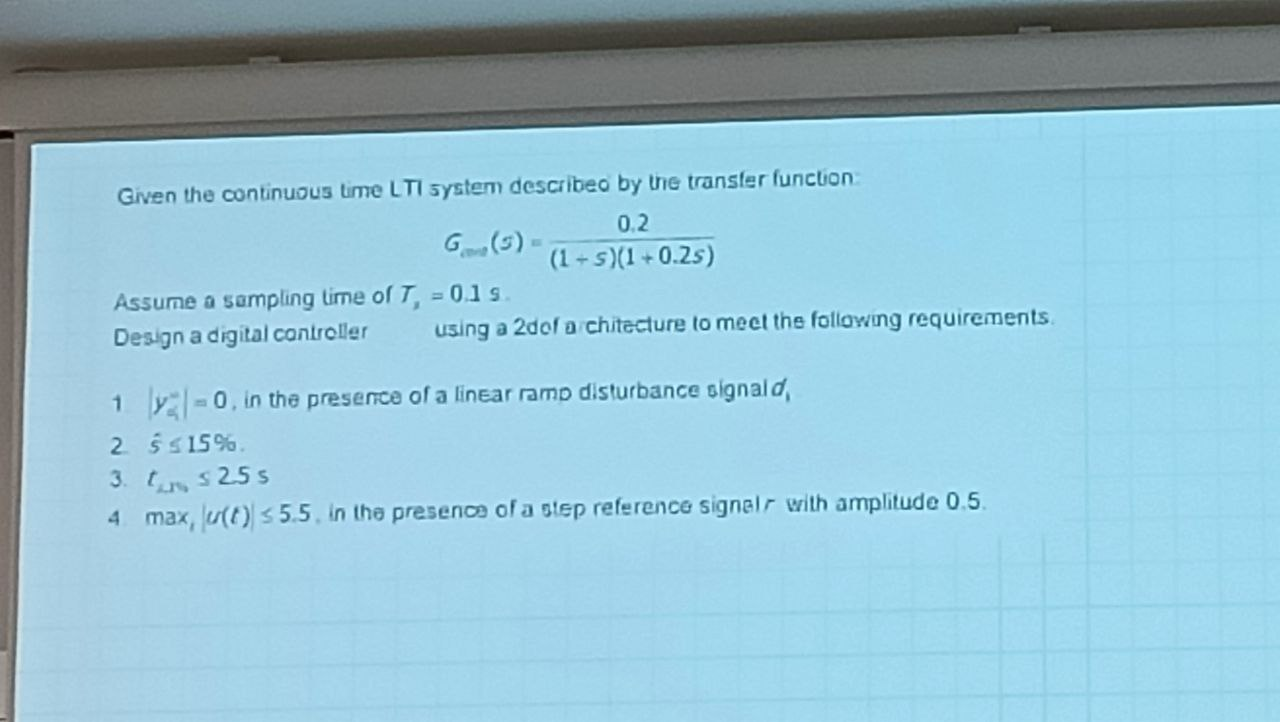

clc
clear all
s = tf('s');
ts = 0.1;
d1 = 0;
z = tf('z',ts);
G_cont = 0.2/((1+s)*(1+0.2*s));
G_disc = zpk(c2d(G_cont,ts,'zoh'))

G_disc =
 
  0.0041172 (z+0.8189)
  ---------------------
  (z-0.9048) (z-0.6065)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



[z_G, p_G, k_G] = zpkdata(G_disc,'v');
B = k_G*[1 -z_G]

B =     0.0041    0.0034


A = conv([1 -p_G(1)],[1 -p_G(2)])

A =     1.0000   -1.5114    0.5488



$$d_1 =T_s k\epsilon \left(k\right)\to l_2 =2\to C\left(z\right)=\frac{S\left(z\right)}{{\left(z-1\right)}^2 R^{\prime } \left(z\right)}$$


La condizione sull'overshoot mi da lo smorzamento $\zeta$:

s_hat = 0.15;
zeta = abs(log(s_hat))/(sqrt(pi^2 + (log(s_hat))^2))

zeta = 0.5169

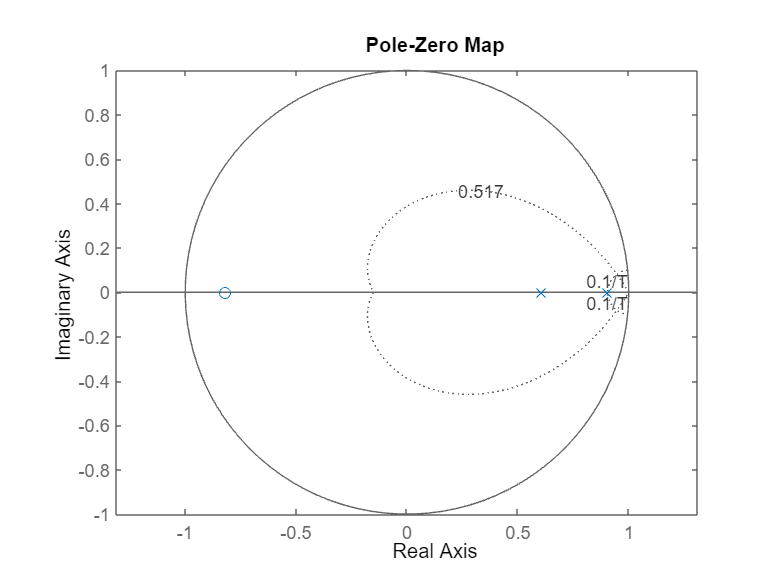

t_s1 = 2.5;
wn = 4.6/(zeta*t_s1);
figure
pzmap(G_disc)
axis('equal')
zgrid(zeta,ts)

Effettuo le cancellazioni zero-polo nella zona $\zeta \ge 0\ldotp 5169$

**DESIGN SETTINGS**

A_plus = A;
B_plus = 1;
A_minus = 1;
B_minus = B;

Quindi $\begin{array}{l}
C\left(z\right)\;=\frac{A^+ \left(z\right)S^{\prime } \left(z\right)}{{\left(z-1\right)}^2 R^{\prime } \left(z\right)}\to \deg \left(S^{\prime } \left(z\right)\right)=1,\deg \left(R^{\prime } \left(z\right)\right)=1,\deg \left(A_m \left(z\right)\right)=3\ldotp \\
S^{\prime } \left(z\right)=s_1 z+s_0 \;\\
R^{\prime } \left(z\right)=r_1 z+r_0 \\
A_m \left(z\right)=z^3 +p_2 z^2 +p_1 z+p_0 
\end{array}$

Definisco i poli voluti:

p1_c = -zeta*wn + j*wn*sqrt(1-zeta^2); %#ok<*IJCL> 
p2_c = -zeta*wn - j*wn*sqrt(1-zeta^2);
p3_c = -5*zeta*wn;
p1 = exp(ts*p1_c);
p2 = exp(ts*p2_c);
p3 = exp(ts*p3_c);
A_m = poly([p1 p2 p3])

A_m =     1.0000   -1.9857    1.3247   -0.2758


**DIOPHANTINE EQUATIONS**

A_dioph = conv(A_minus,conv([1 -1],[1 -1]))

A_dioph =      1    -2     1


B_dioph = B_minus

B_dioph =     0.0041    0.0034


DEFINISCO LA MATRICE $M_s$:

M_s = [[A_dioph(:);0],[0;A_dioph(:)],[0;B_dioph(:);0], [0;0;B_dioph(:)]]

M_s =     1.0000         0         0         0
   -2.0000    1.0000    0.0041         0
    1.0000   -2.0000    0.0034    0.0041
         0    1.0000         0    0.0034


Gamma = A_m';
theta = M_s\Gamma;
R1 = theta(1:2)';
S1= theta(3:4)';
R = conv([1 -2  1], R1)

R =     1.0000   -2.1608    1.3217   -0.1608


S = conv(A_plus, S1)

S =    42.5277  -98.3782   74.8822  -18.7162


C = zpk(tf(S,R,ts))

C =
 
  42.528 (z-0.9048) (z-0.8019) (z-0.6065)
  ---------------------------------------
            (z-1)^2 (z-0.1608)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



L = minreal(C*G_disc,1e-4)

L =
 
  0.17509 (z-0.8019) (z+0.8189)
  -----------------------------
       (z-0.1608) (z-1)^2
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



Wprime=zpk(minreal(L/(1+L),1e-4))

Wprime =
 
    0.17509 (z-0.8019) (z+0.8189)
  ----------------------------------
  (z-0.3985) (z^2 - 1.587z + 0.6921)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



DESIGN OF $F^{\prime } \left(z\right)=\frac{T^{\prime } \left(z\right)}{S^{\prime } \left(z\right)}\to \deg \left(S^{\prime } \right)=1\to \deg \left(T^{\prime } \right)=1\to T^{\prime } \left(z\right)=k_T \tilde{T} \left(z\right)\to T^{\prime } \left(z\right)=k_T A^0 \left(z\right),\textrm{scegliamo}\;k_w =1\;\left(\textrm{scelta}\;\textrm{nostra}\;\textrm{perchè}\;\textrm{nelle}\;\textrm{nostre}\;\textrm{richieste}\;\textrm{non}\;è\;\textrm{richiesto}\;\textrm{di}\;\textrm{imporre}\;a\;\textrm{zero}\;l^{\prime } \textrm{errore}\;\textrm{di}\;\textrm{inseguimento}\;\right)$

T_tilde = [1 -p3]

T_tilde =     1.0000   -0.3985


kW = 1;
kT = kW*polyval(S1,1)/(polyval(T_tilde,1)*dcgain(Wprime));
T1 = kT*T_tilde;
F = zpk(tf(T1,S1,ts))

F =
 
  0.32934 (z-0.3985)
  ------------------
      (z-0.8019)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



rho = 1;
t_sim = 10;
out = sim('DC_7b')

out =   Simulink.SimulationOutput:

                   tout: [100003x1 double] 
                      u: [1x1 timeseries] 
              u_sampled: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


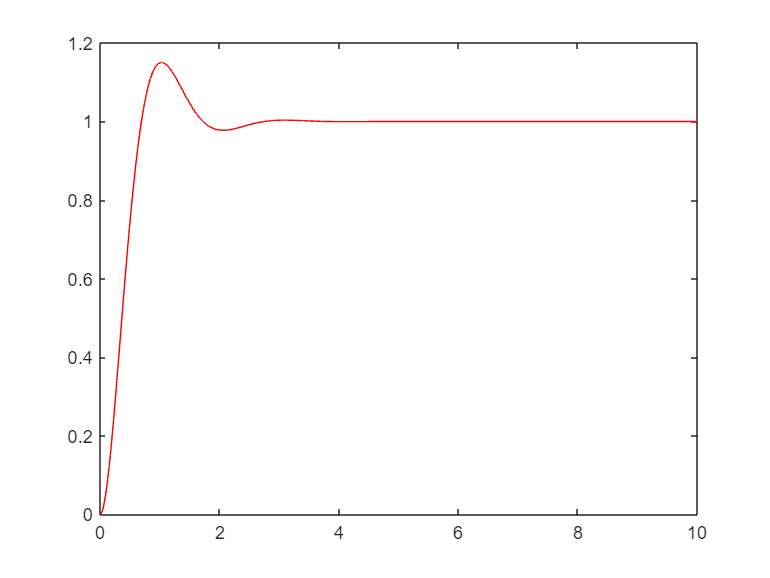

figure
plot(out.y.time, out.y.data, 'r')

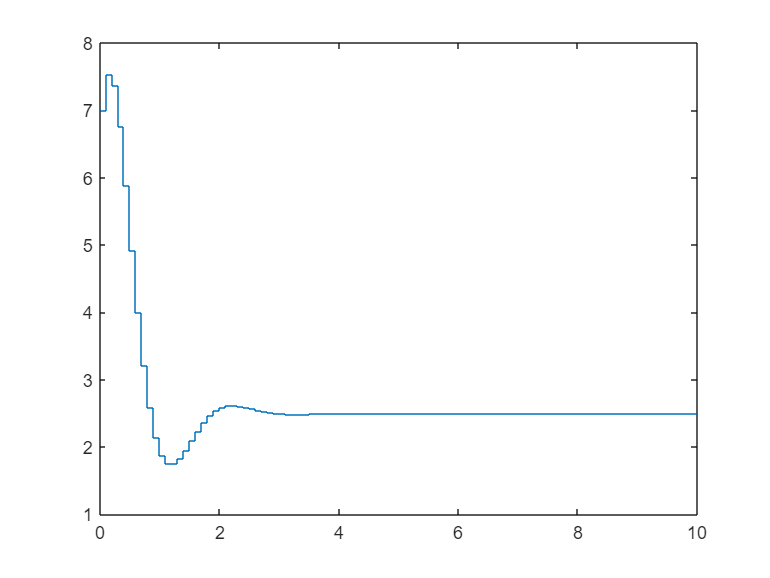

figure
stairs(out.u_sampled.time, 0.5*out.u_sampled.data) %0.5 per la richiesta 4 con lo step

Aumentando $w_n \;\textrm{si}\;\textrm{ha}\;\textrm{che}\;\textrm{il}\;\textrm{valore}\;\textrm{massimo}\;\textrm{di}\;u\left(k\right)\;\textrm{diminuisce}$

zeta = abs(log(s_hat))/(sqrt(pi^2 + (log(s_hat))^2))*1.2

zeta = 0.5169